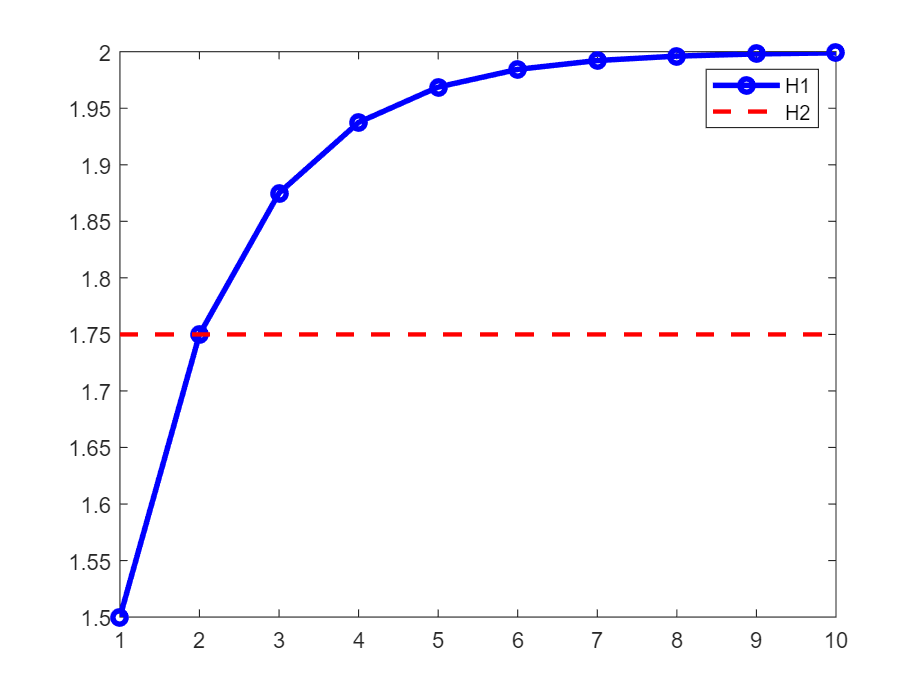

%绘制线性调频函数拟合化简公式 H1, H2
clear all;
close all;
K = 2;
f = 60;
B = 180;
n = 1:10;
H1 = K + (1-K)*cos(pi * f/ B).^n;
figure(1)
plot(n, H1,'-ob', LineWidth=2.5);
hold on;
h2 = (1+K)/2 + (1-K)/4*(exp(j*2*pi*f/B)+exp(-j*2*pi*f/B));
H2 = ones(size(n))*h2;
plot(n, H2, 'r--', LineWidth=2);
hold off;
legend("H1", "H2")

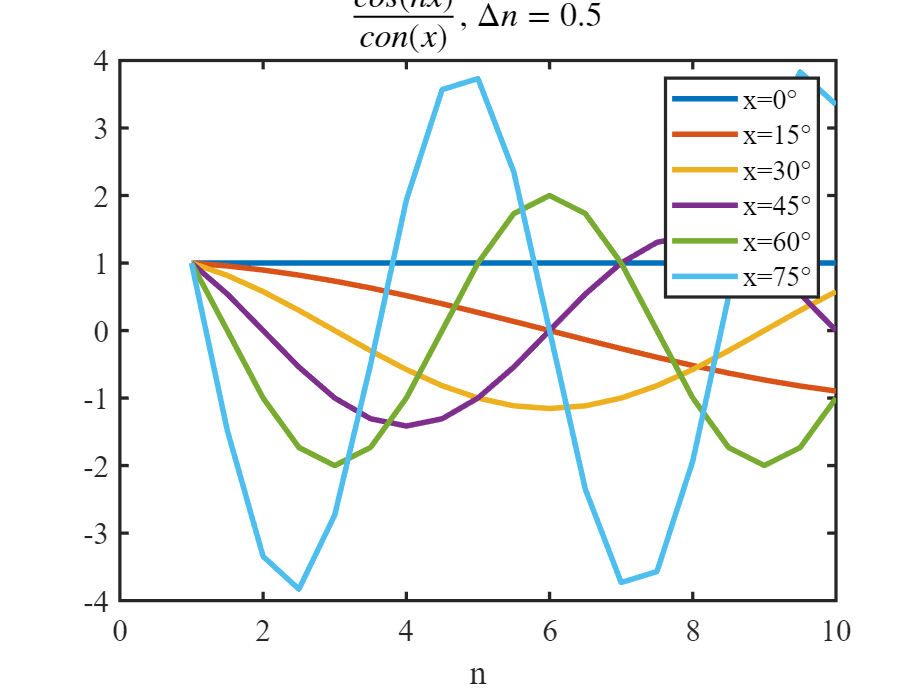

% 拟合cos(nx)/cos(x)的关系
clear all;
close all;

x = 0:15:90-1;
n = 1:0.5:10;
for i = 1:length(x)
    H(i,:) = cosd(n*x(i))/cosd(x(i));   
    plot(n, H(i, :), LineWidth=2.5);
    hold on;
    leg_str(i) = sprintf("x=%d°", x(i));
end
legend(leg_str)
xlabel('n')
title('$\frac{cos(nx)}{con(x)}$, $\Delta n=0.5$', Interpreter='latex')
set(gca,'FontName','Times New Roman','FontSize',14,'LineWidth',1.5);